## Genera una función que tenga como entrada la señal PCG correspondiente a un latido y que, basado en la extracción de parámetros de las distintas estimaciones espectrales y RTF, tenga como salida una estimación de las características temporales y frecuenciales de cada componente del PCG, haciendo énfasis en la caracterización y diferenciación de los distintos tipos de sonidos o componentes de la señal PCG correspondientes a las distintas patologías analizadas. 

Uncomment the following line and defint the type variable with one label to manually overide the classification method.

% signals = [normal, diastolic, sysregurg, ejecmur];
% labels = ["NORMAL", "DFS2", "SMR", "ER"];
% 
% type = "ER";
% representationtype = "TFR";
% index = find(ismember(labels,type));
% signal = signals(:,index);



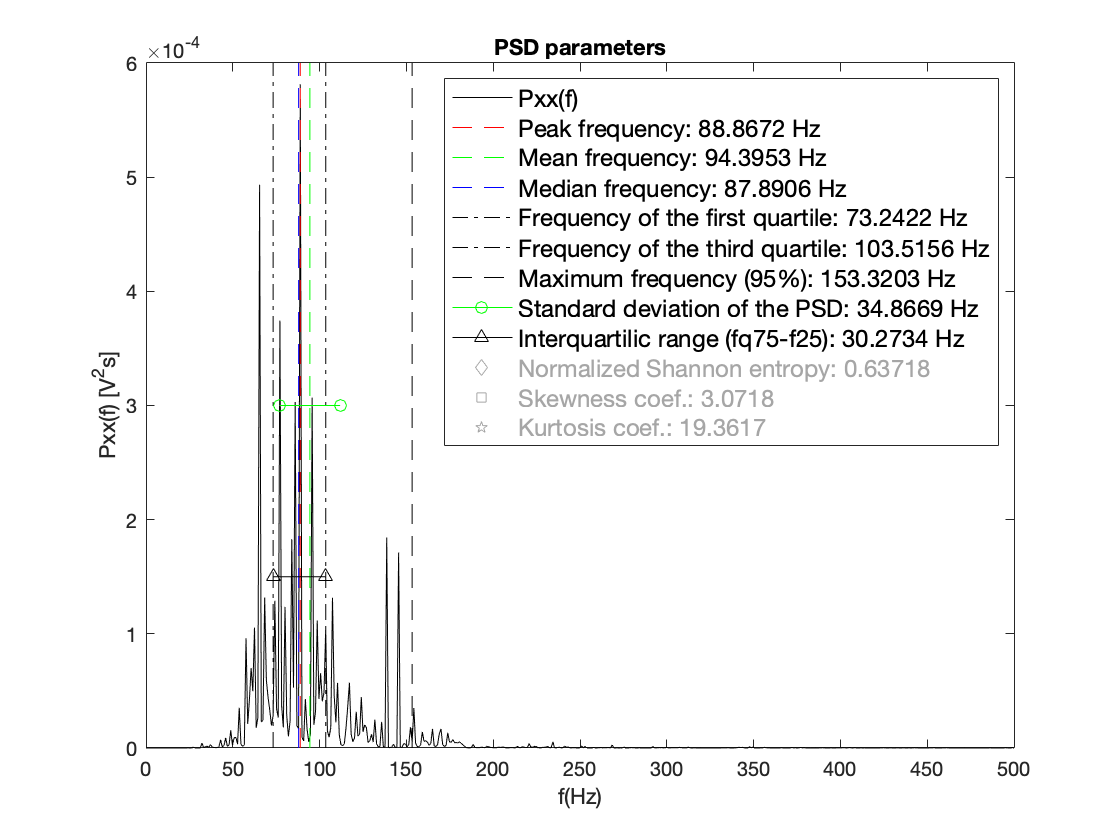

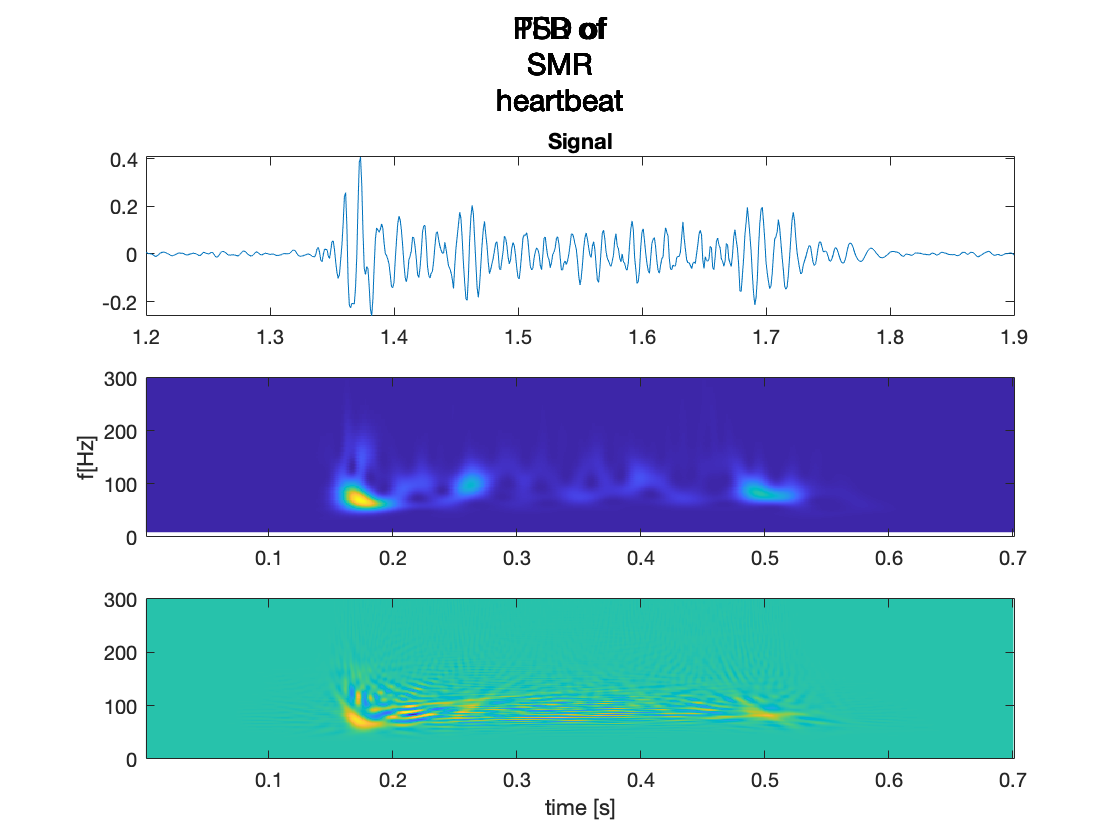

% Matrix of centroids to compare with euclidean distance with new cases
PSDparam = [cell2mat(struct2cell(PSDpar_normal))';cell2mat(struct2cell(PSDpar_diast))'; cell2mat(struct2cell(PSDpar_systo))';cell2mat(struct2cell(PSDpar_eject))'];

%Type of representation
representationtype = "TFR";

%Algorithm
[~]=algorithm(sysregurg,PSDparam, t_sysregurg, representationtype)

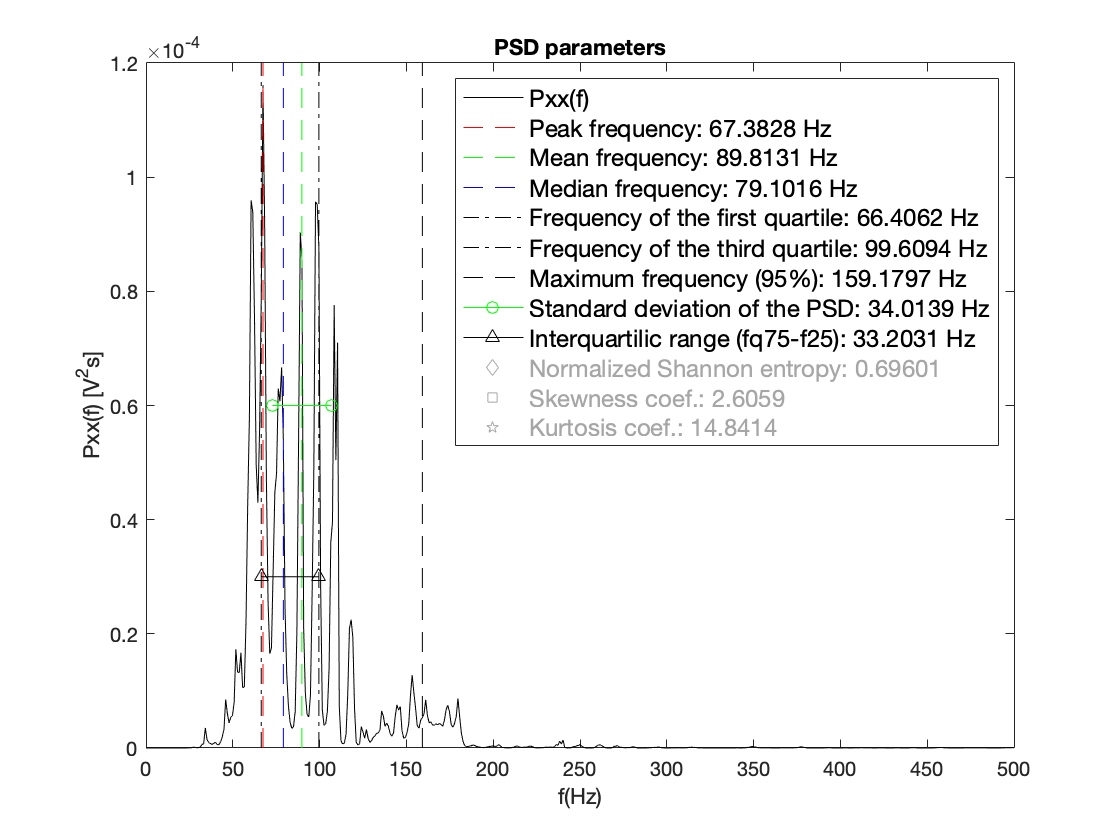

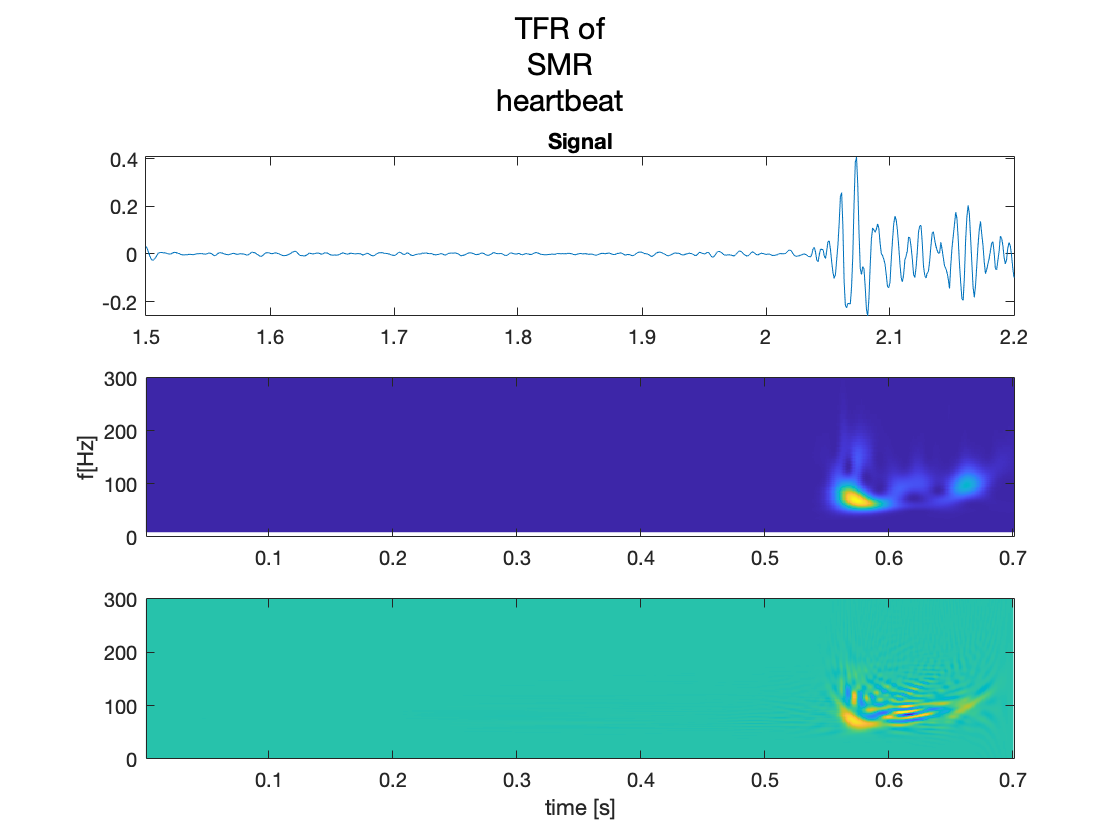


%Random part of a signal to process
signal =sysregu(tsys>=0.8 & tsys<=1.5); %we have to get the whole 10 heartbeat signal
representationtype ="TFR";
[~]=algorithm(signal,PSDparam, t_normal, representationtype)